# 3D Printer Data Exploration

## Load Data

clear;
load 'houseprint';

## Test Log Data

Look at the acceleration data straight from the file

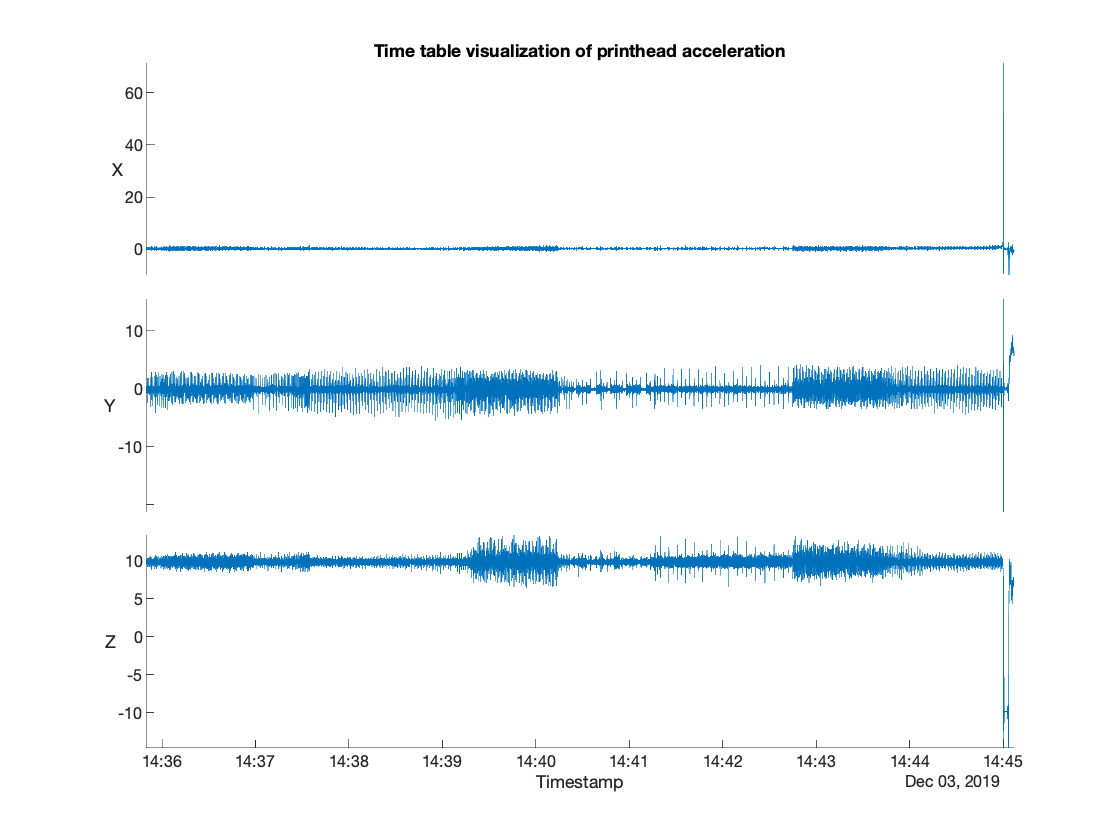

figure()
stackedplot(Acceleration);
title("Time table visualization of printhead acceleration")

## Data Examination - Wave forms

Separate into a regular subplot figure, so that we can zoom into each part to identify important frequencies.

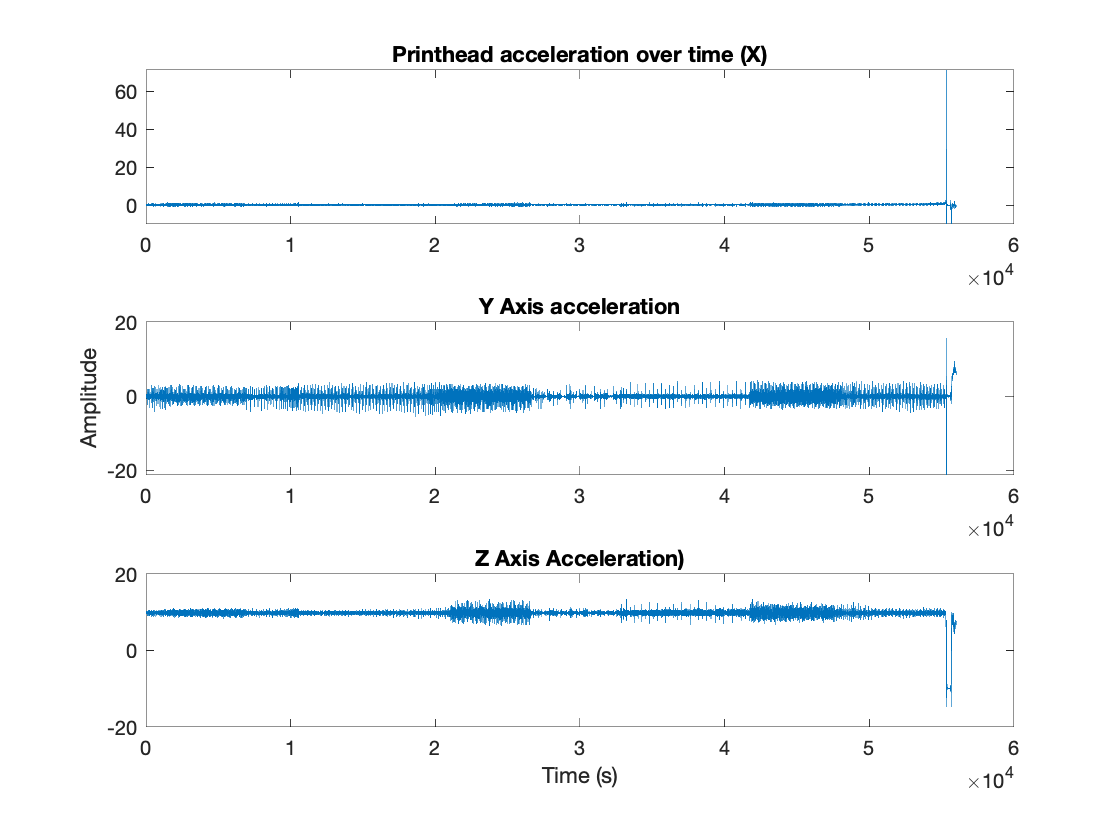

figure()
a = timetable2table(Acceleration);
accelData = [a.X a.Y a.Z]';
subplot(3,1,1);
plot(accelData(1,:))
title("Printhead acceleration over time (X)")
subplot(3,1,2);
plot(accelData(2,:))
title("Y Axis acceleration")
ylabel("Amplitude")
subplot(3,1,3);
plot(accelData(3,:))
title("Z Axis Acceleration)")
xlabel("Time (s)")

## Data Examination - FFT time!

Look at the fft of the data without any filtering, firstly, the normalized magnitude of all the axes

### Normalized

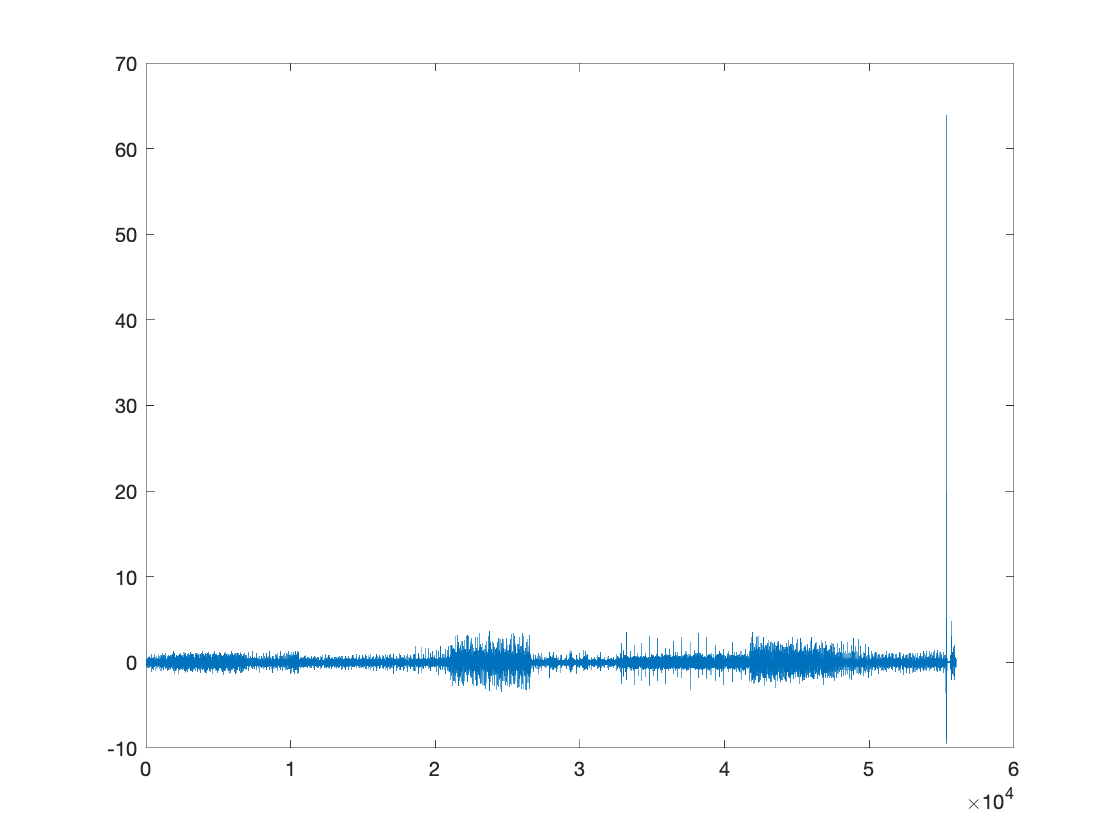

figure()
a = timetable2table(Acceleration);
accelData = [a.X a.Y a.Z]';
x = vecnorm(accelData);
x = x - mean(x);
plot(x)

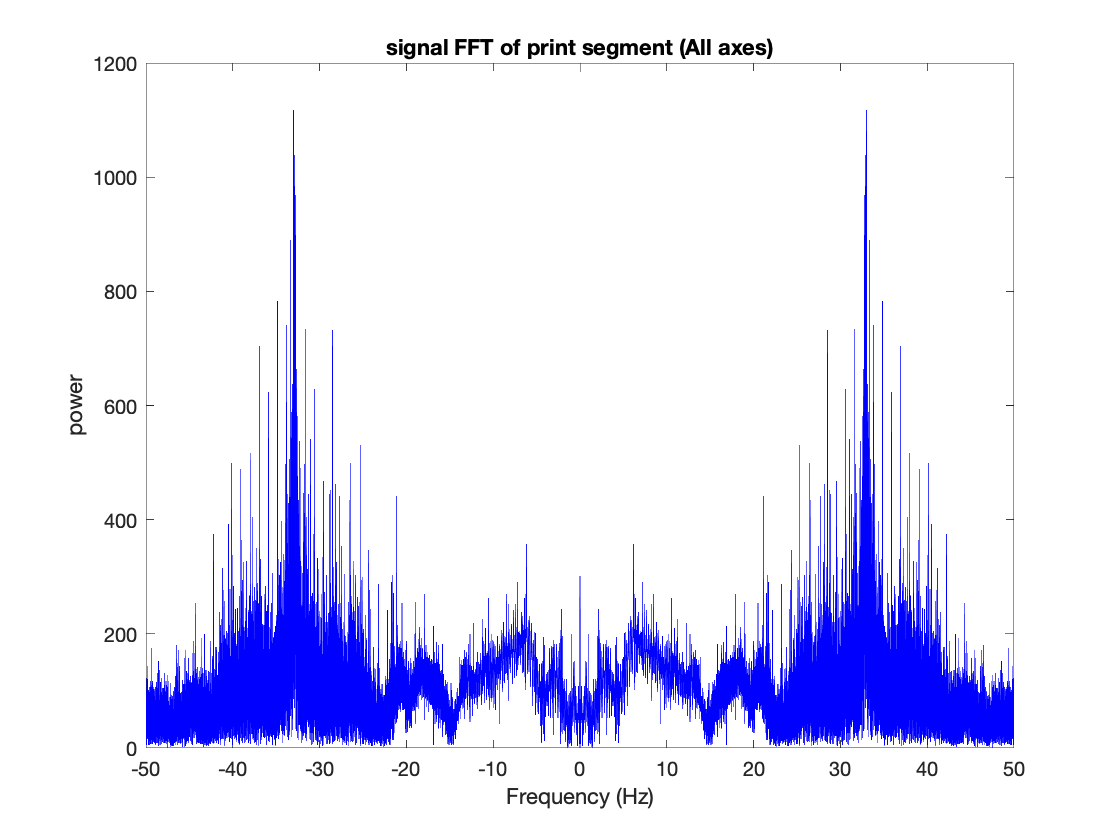

% x = accelData(:,1);
N = length(x);
Fs = 100;
f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);
FA = fft(x);
plot(f,fftshift(abs(FA)),'b');
title("signal FFT of print segment (All axes)")
xlabel("Frequency (Hz)")
ylabel("power")

### X Axis FFT

figure()
subplot(3,1,1);
a = timetable2table(Acceleration);
accelData = [a.X a.Y a.Z]';
x = accelData(1,:);
x = x - mean(x);
plot(x)
% x = accelData(:,1);
N = length(x);
Fs = 100;
f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);
FA = fft(x);
plot(f,fftshift(abs(FA)),'b');
title("X Axis signal FFT of print segment")


### Y Axis FFT

subplot(3,1,2);
a = timetable2table(Acceleration);
accelData = [a.X a.Y a.Z]';
x = accelData(2,:);
x = x - mean(x);
plot(x)
% x = accelData(:,1);
N = length(x);
Fs = 100;
f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);
FA = fft(x);
plot(f,fftshift(abs(FA)),'b');
title("Y Axis signal FFT of print segment")


### Z Axis FFT

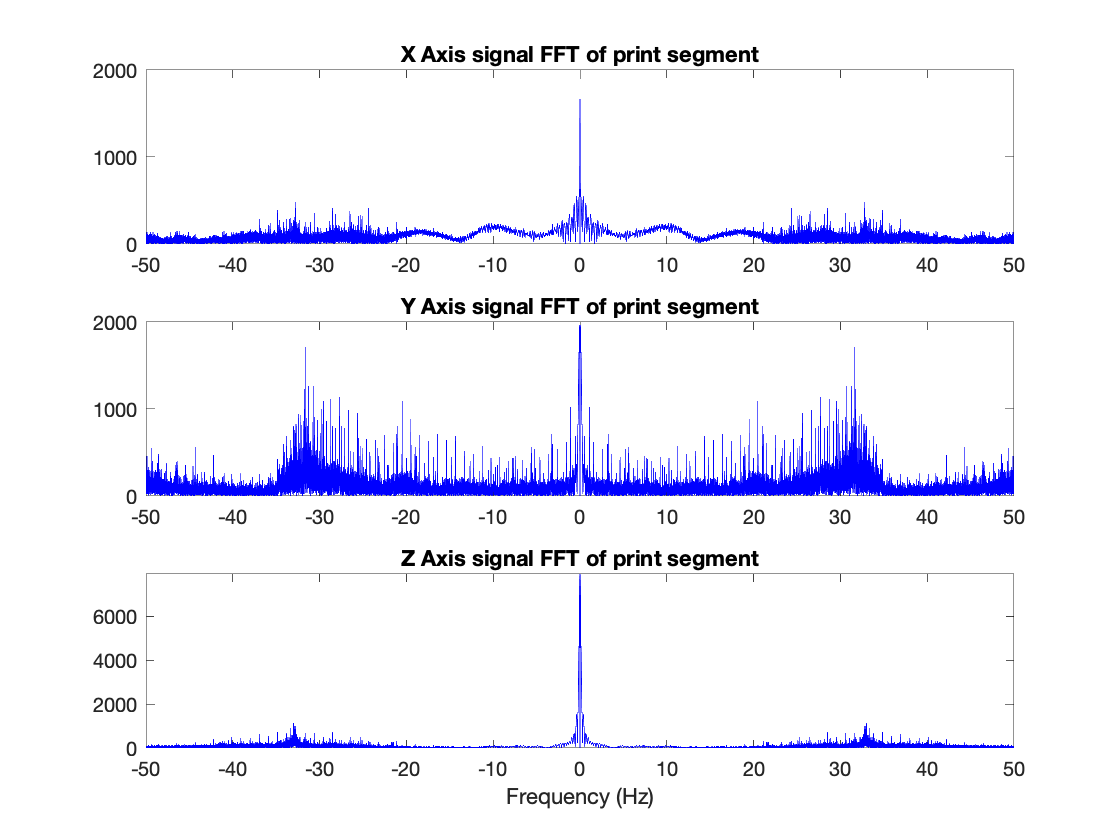

subplot(3,1,3);
a = timetable2table(Acceleration);
accelData = [a.X a.Y a.Z]';
x = accelData(3,:);
x = x - mean(x);
plot(x)
% x = accelData(:,1);
N = length(x);
Fs = 100;
f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);
FA = fft(x);
plot(f,fftshift(abs(FA)),'b');
title("Z Axis signal FFT of print segment")
xlabel("Frequency (Hz)")